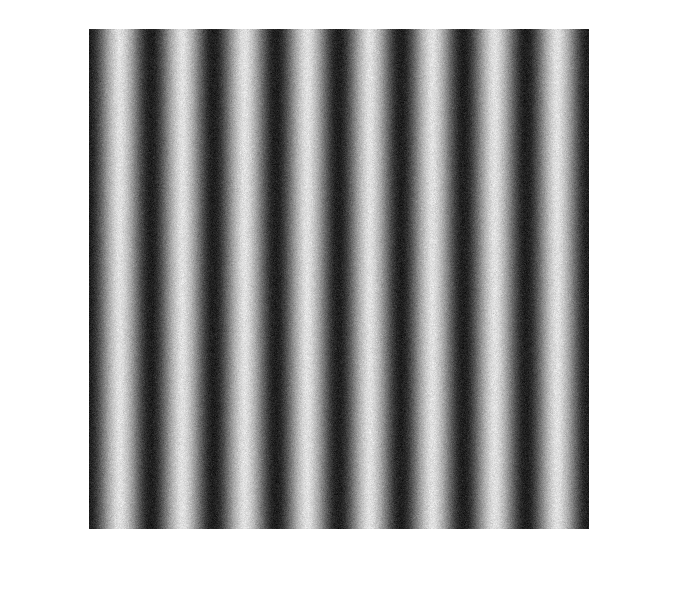


%      img = 0.5*ones(height,width);
%         for a = 1:width
%             for b = 1:height
%                 for i=1:k_h
%                 img(b,a) = img(b,a)+amp_harm(i)*cos(i*(fre*(a)+phi+delta_phi(b,a)));
%     
%                 end
%             end
%         end
%     for m=1:fre
% 
%         
% for n=1:step
%     phi=2*pi*(n-4)/step;
%  First=fringeModulation(u(m),phi,deltphi{m},height,width,noisy,noisy_value_guassian);
%  
%   path=['E:\liyimingPCL\博士课题\实验记录-源代码+过程\3.14-基本工件几何体仿真\code\new\test\',num2str(m), '_',num2str(n),'.mat'];
%  save(path, 'First');
% %  save(path, 'First');
% end
% end
clc
clear all
clf
scale=500;
height=scale;%图片的高是矩阵的第一维
width=scale;%图片的宽是矩阵的第二维
T=[width,width/2,width/4,width/8]; % 参数单位 mm
u=[2*pi/T(1),2*pi/T(2),2*pi/T(3),2*pi/T(4)];


k_value=0.1;
% amp_harm = [k_value/1, k_value/2, k_value/5, k_value/10, k_value/20,k_value/100]; % 四次谐波振幅
% amp_harm = [0.4, 0.02, -0.02, -0.02, 0.03,0.01];
amp_harm = [k_value*2, k_value*0.01, k_value*0.04, k_value*0.02, k_value*0.01,k_value*0.01]; % 四次谐波振幅
k_h=6;
 phi=[2*pi*(1-4)/6,2*pi*(2-4)/6,2*pi*(3-4)/6,2*pi*(4-4)/6,2*pi*(5-4)/6,2*pi*(6-4)/6];

 img = 0.5*ones(height,width);
        for a = 1:width
            for b = 1:height
                for i=1:k_h
                img(b,a) = img(b,a)+amp_harm(i)*cos(i*(u(4)*(a)+phi(1)));
    
                end
            end
        end
         img=img+imnoise(img,'gaussian',0,0.001);
       figure
      

     imshow(img,[]);

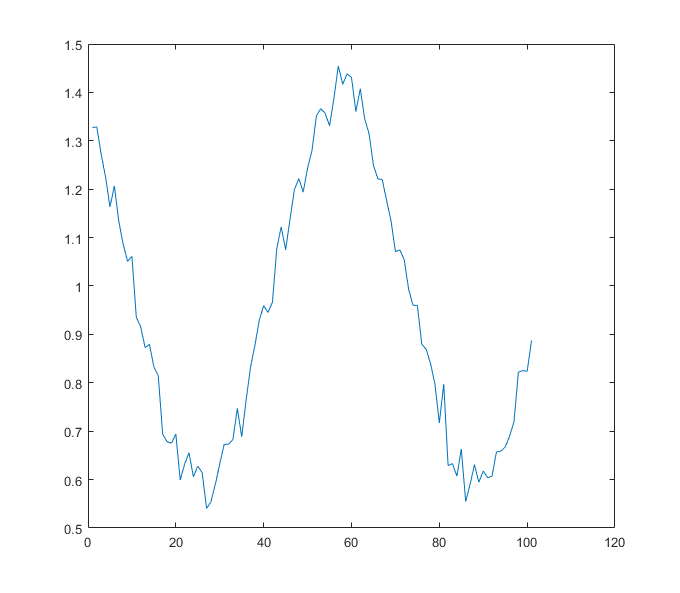

     plot(img(scale/2,100:200));

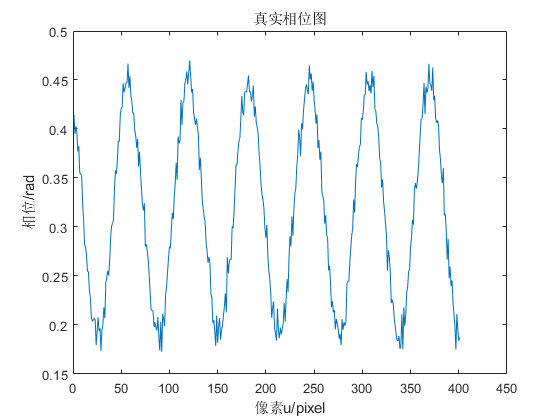

     figure;
     plot(img(200,100:500)/pi);xlabel('像素u/pixel');ylabel('相位/rad'); 
     title('真实相位图')





% A=imread('E:\liyimingPCL\博士课题\实验记录-源代码+过程\MEMS三维测量\2023.03.27李壮\reconstruction\reconstruction\plane\3\3_1.bmp');
% figure;
% imshow(A,[]);
% 
% plot(A(200,100:500)/pi);xlabel('像素u/pixel');ylabel('相位/rad'); 
% title('真实相位图')
% figure;
% plot(A(200,100:200)/pi);xlabel('像素u/pixel');ylabel('相位/rad'); 
% title('真实相位图')
%    